clear;clc;close all;

**OFDM Parameters**

nfft = 1024;
BW = 250000;
Fc = 250000;
M = 16;
ofdm_symbols = 10;
Interp_val = 40;
cp_len = nfft/4;
rep = 4;
snr = 30;
multi = [1 0.1 0.05 0 0 0 1.2 0.9];
pilot_index = 2:rep:1022;
zp_index = [1,1023:1024];
%pilot_index = 112:rep:912;
%zp_index = [1:111,913:1024];
nfft_p = 16*nfft;

**Calculated Parameters;**

data_index = 1:nfft;
data_index([pilot_index,zp_index]) = [];
F = (-nfft_p/2:nfft_p/2-1)/nfft_p*BW;
F = F/1000; % in kHz
t_up = 0:1/BW/Interp_val:((nfft+cp_len)*ofdm_symbols-1/BW)*1/BW;
F_up = (-nfft_p/2:nfft_p/2-1)/nfft_p*BW*Interp_val;
F_up = F_up/1000;

**OFDM Modulate:**

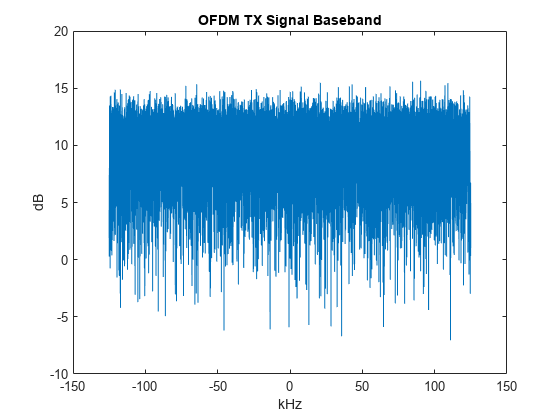

[ofdm_signal,P,mod_data,t,t2,freq_signal] = ofdm_transmit(nfft,BW,M,cp_len, ...
    ofdm_symbols,zp_index,pilot_index,0,1,1);

figure(),plot(F,10*log10(abs(fftshift(fft(ofdm_signal,nfft_p))))),title('OFDM TX Signal Baseband')
xlabel('kHz'),ylabel('dB')

**DUC:**

ofdm_duc_signal = interp(ofdm_signal,Interp_val,10,1);
ofdm_duc_signal = ofdm_duc_signal.';

**IQ Mixer:**

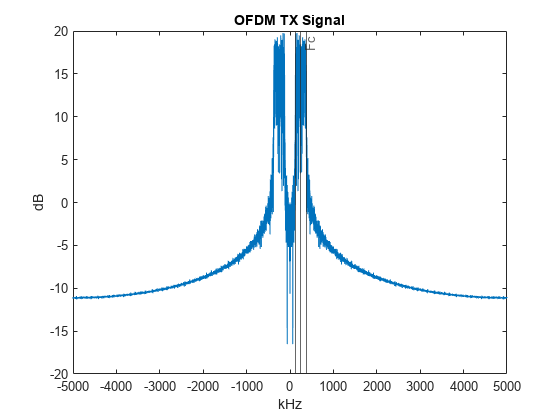

ofdm_duc_signal_i = real(ofdm_duc_signal) .* cos(2*pi*Fc*t_up);
ofdm_duc_signal_q = imag(ofdm_duc_signal) .* -sin(2*pi*Fc*t_up);
ofdm_duc_signal_real = ofdm_duc_signal_i + ofdm_duc_signal_q;

figure(),plot(F_up,10*log10(abs(fftshift(fft(ofdm_duc_signal_real,nfft_p))))),title('OFDM TX Signal')
xlabel('kHz'),ylabel('dB'),xline([(Fc-BW/2)/1000 Fc/1000 (Fc+BW/2)/1000],'-',{' ','Fc',' '})

**Channel:**

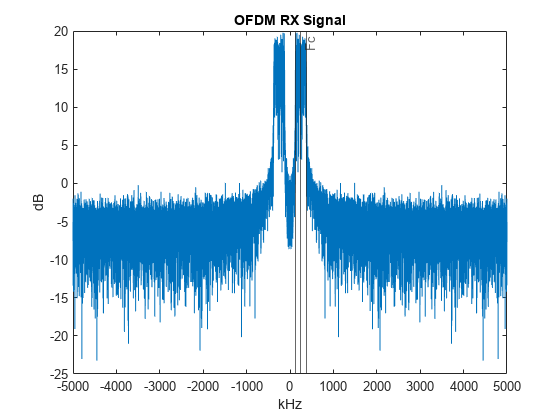

[ofdm_signal_ch,nvar] = awgn(ofdm_duc_signal_real,snr,'measured');
%ofdm_signal_ch = filter(multi,1,ofdm_signal_ch);

figure(),plot(F_up,10*log10(abs(fftshift(fft(ofdm_signal_ch,nfft_p))))),title('OFDM RX Signal')
xlabel('kHz'),ylabel('dB'),xline([(Fc-BW/2)/1000 Fc/1000 (Fc+BW/2)/1000],'-',{' ','Fc',' '})

**IQ Mixer:**

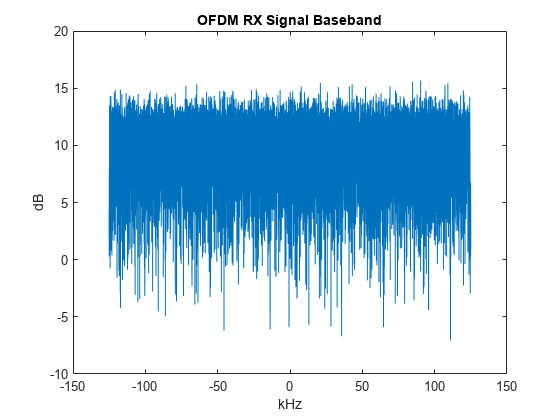

ofdm_ddc_signal_i = ofdm_signal_ch .* cos(2*pi*Fc*t_up);
ofdm_ddc_signal_q = ofdm_signal_ch .* -sin(2*pi*Fc*t_up);
ofdm_ddc_signal = complex(ofdm_ddc_signal_i,ofdm_ddc_signal_q);

figure(),plot(F,10*log10(abs(fftshift(fft(ofdm_signal,nfft_p))))),title('OFDM RX Signal Baseband')
xlabel('kHz'),ylabel('dB')

**DDC:**

ofdm_ddc_signal = decimate(ofdm_ddc_signal,Interp_val,512,'fir');

**OFDM Demodulate:**

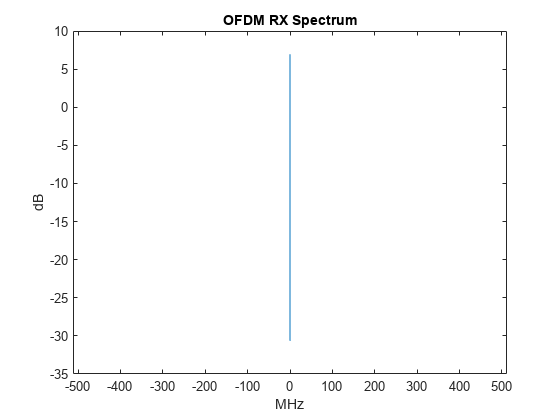

ans = 4×4 table
                           Equalization                             SER      AverageEVM    PeakEVM
    __________________________________________________________    _______    __________    _______

    "No Equalization, No CFO Correction"                          0.75948      52.269      101.29 
    "Interpolated Windowed ZF Equalization, No CFO Correction"          0      1.9223      20.024 
    "No Equalization, CFO Correction"                             0.75948      52.269      101.29 
    "Interpolated Windowed ZF Equalization, CFO Correction"             0       1.921       20.03 


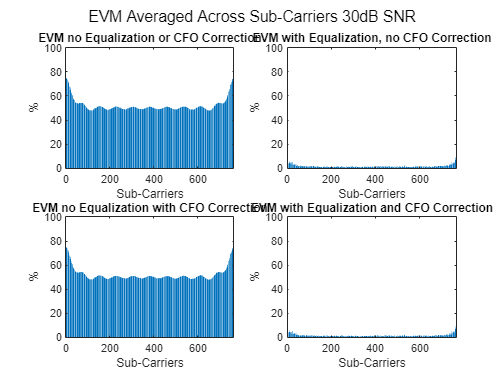

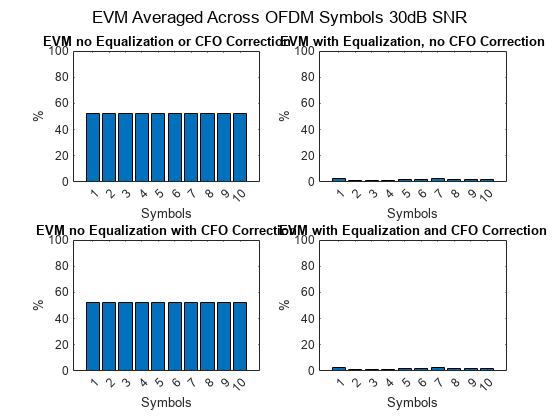

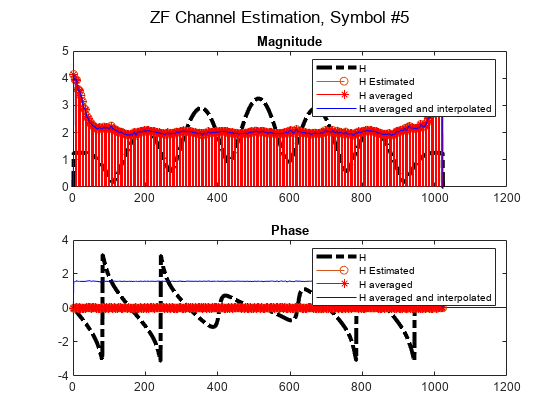

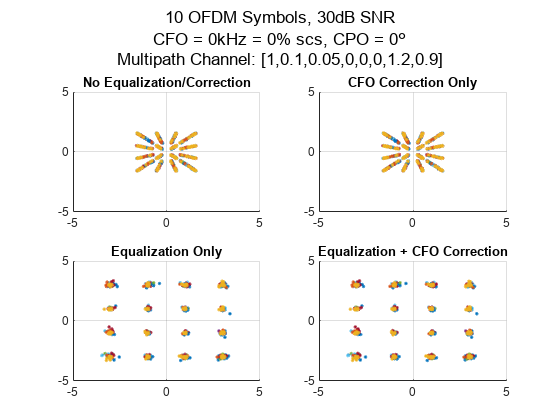

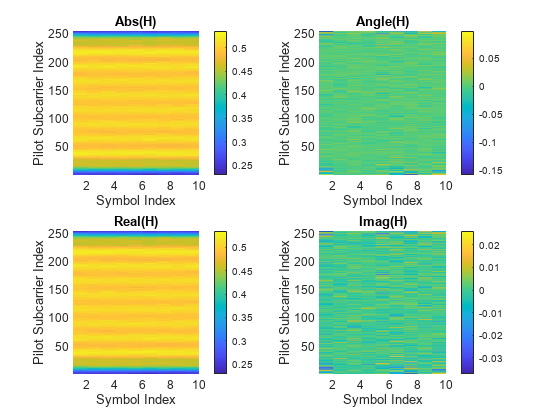

[dmod,ser] = ofdm_receive(ofdm_ddc_signal,P,nfft,BW,M,cp_len,ofdm_symbols,zp_index, ...
    pilot_index,rep,mod_data,[1 1],freq_signal,0,multi,snr,0,nvar,1,5,ofdm_signal);

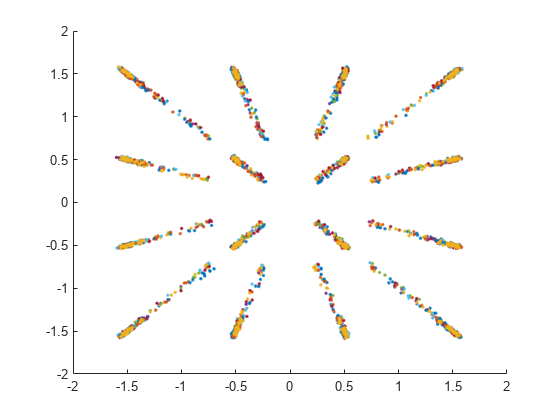

ofdm_rx_signal_ch = reshape(ofdm_ddc_signal,[nfft+cp_len ofdm_symbols]);

cp_rm_signal = ofdm_rx_signal_ch;
cp_rm_signal(1:cp_len,:) = [];
fft_signal = fftshift(fft(cp_rm_signal,nfft));

fft_signal([pilot_index,zp_index],:) = [];

figure(),scatter(real(fft_signal),imag(fft_signal),'.')